# section 1

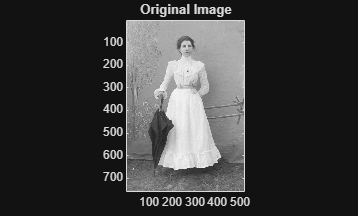

img = imread('vintage_postcard.tif');
img = im2double(img);

figure;
imagesc(img);
colormap(gray);
axis image;
title('Original Image');

## section 2

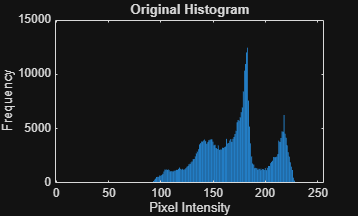

pixels = round(img * 255) + 1;

H = histcounts(pixels(:), 1:257);

figure;
bar(0:255, H);
title('Original Histogram');
xlabel('Pixel Intensity');
ylabel('Frequency');

## 3. Cumulative Histogram

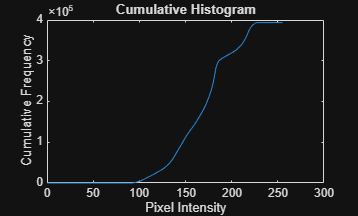

C = cumsum(H);

figure;
plot(0:255, C);
title('Cumulative Histogram');
xlabel('Pixel Intensity');
ylabel('Cumulative Frequency');

## 4. First Nonzero Histogram Entry

H0 = H(find(H > 0, 1));

disp(H0);

     1



## 5. Histogram Equalization Mapping

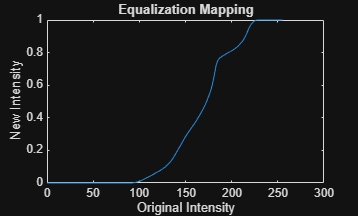

if numel(img) == H0
    mapping = zeros(size(C));
else
    mapping = (C - H0) / (numel(img) - H0);
    mapping = max(0, mapping);
end

figure;
plot(0:255, mapping);
title('Equalization Mapping');
xlabel('Original Intensity');
ylabel('New Intensity');

## 6. Apply Histogram Equalization

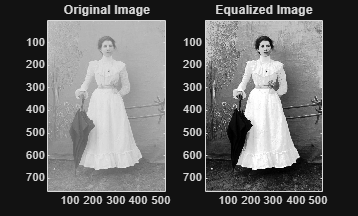

eq_img = reshape(mapping(pixels), size(img));

figure;
subplot(1, 2, 1);
imagesc(img);
caxis([0 1]);
title('Original Image');
axis image;

subplot(1, 2, 2);
imagesc(eq_img);
caxis([0 1]);
title('Equalized Image');
axis image;

colormap(gray);

## 7. Compare Histograms

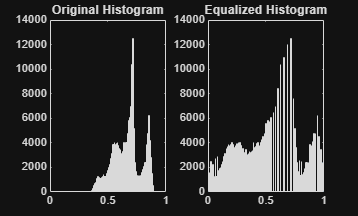

figure;

subplot(1, 2, 1);
histogram(img(:), 256, 'BinLimits', [0 1]);
title('Original Histogram');
xlim([0 1]);

subplot(1, 2, 2);
histogram(eq_img(:), 256, 'BinLimits', [0 1]);
title('Equalized Histogram');
xlim([0 1]);